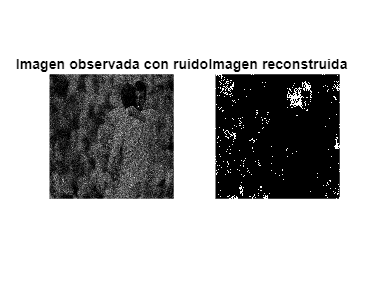

% Cargar la imagen observada con ruido (simulada)
imagen_observada = imread('im_3_level_10.png'); % Debes tener tu propia imagen con ruido

% Convertir la imagen a escala de grises (si no está en escala de grises)
if size(imagen_observada, 3) == 3
    imagen_observada = rgb2gray(imagen_observada);
end

% Convertir a tipo double para realizar cálculos
imagen_observada = double(imagen_observada);

% Tamaño de la imagen
[alto, ancho] = size(imagen_observada);

% Parámetros ADMM
max_iter = 100;  % Número máximo de iteraciones
rho = 1;         % Parámetro de ajuste para actualización de multiplicadores de Lagrange
lambda = 0.001;    % Parámetro de regularización (ajustar según la cantidad de suavizado deseada)

% Inicialización
x = ones(alto, ancho); % Suponemos una imagen inicial constante
z = x; % Variables auxiliares
u = zeros(alto, ancho); % Multiplicadores de Lagrange inicializados en cero

% Implementación del algoritmo ADMM
for iter = 1:max_iter
    % Actualización de "x" (minimizar la función de verosimilitud y términos de Lagrange)
    x = exp((imagen_observada + rho*(z-u)) / (1+rho));
    
    % Actualización de "z" (minimizar la función de penalización y términos de Lagrange)
    z_antiguo = z;
    z = umbralSuave(z, lambda / rho);
    
    % Actualización de los multiplicadores de Lagrange "u"
    u = u + x - z;
    
    % Comprobar convergencia
    convergencia = norm(z - z_antiguo, 'fro') / norm(z_antiguo, 'fro');
    if convergencia < 1e-6
        break;
    end
end


% Mostrar resultados
figure;
subplot(1, 2, 1);
imshow(imagen_observada, []);
title('Imagen observada con ruido');

subplot(1, 2, 2);
imshow(x, []);
title('Imagen reconstruida');

function z = umbralSuave(x, umbral)
    z = sign(x) .* max(abs(x) - umbral, 0);
end